Load Original Image

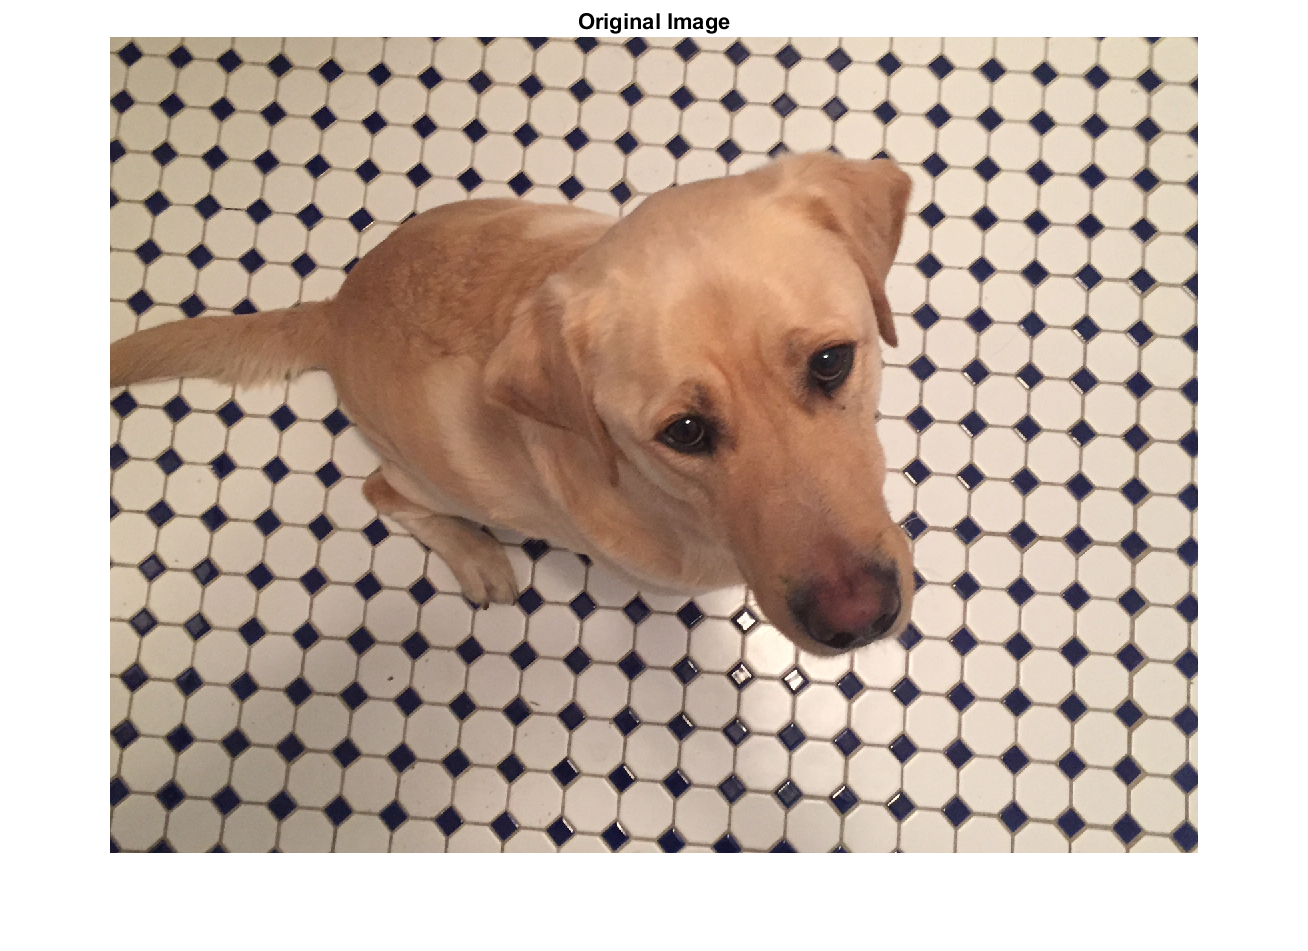

img = imread("kobi.png");
figure;
imshow(img);
title('Original Image');

img_db = im2double(img);

Image segmentation using  K-nearest neighbors

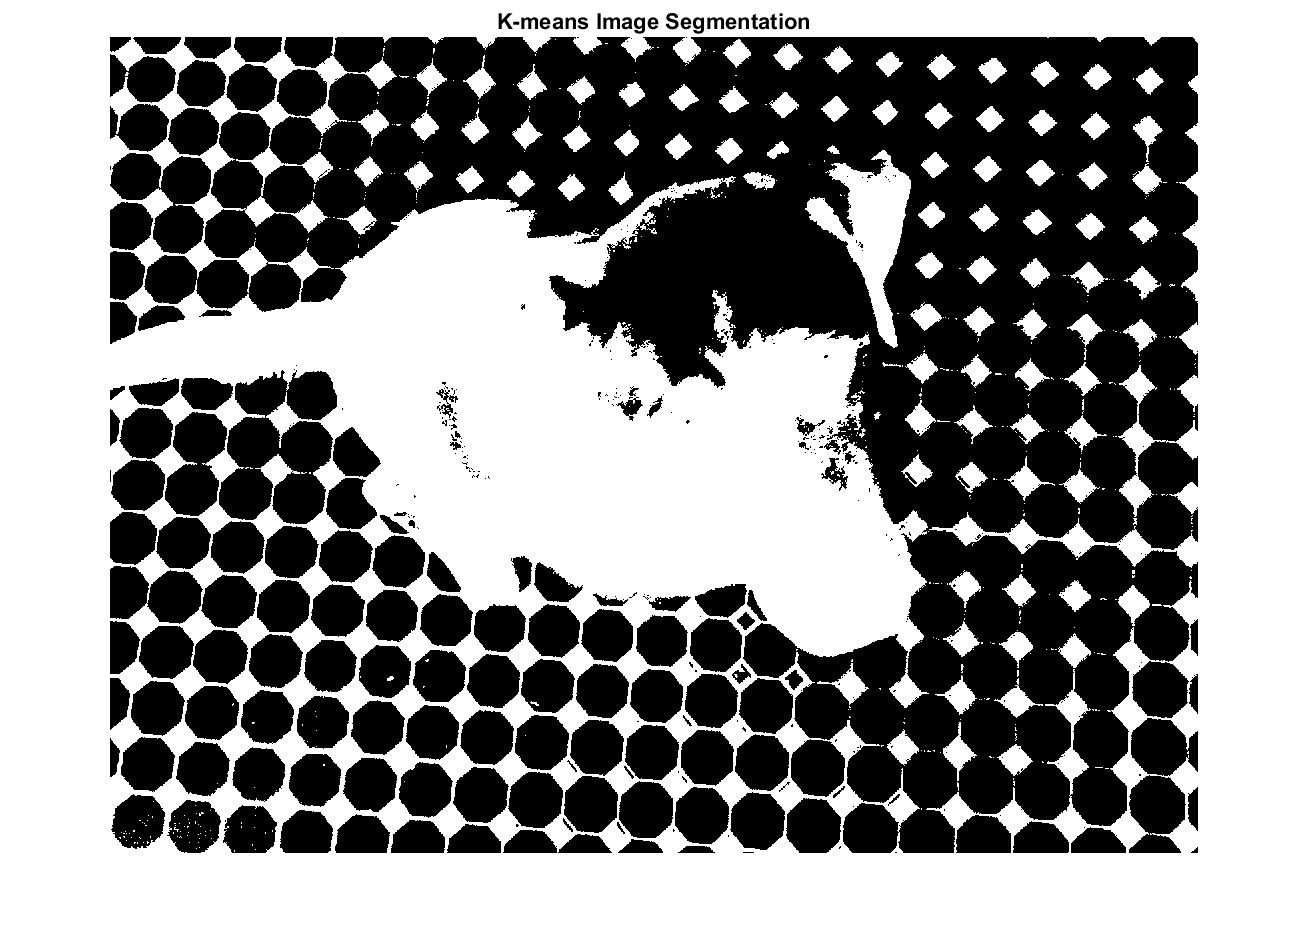

vctr_img = imstack2vectors(img_db);
class_number = 2;
[kmeans_segmentation,c] = kmeans(vctr_img,class_number);
[width,height,bands] = size(img_db);
kmeans_segmentation = reshape(kmeans_segmentation,[width,height]);
figure;
imshow(kmeans_segmentation,[]);
title('K-means Image Segmentation');

Image segmentation using  Super Pixel 

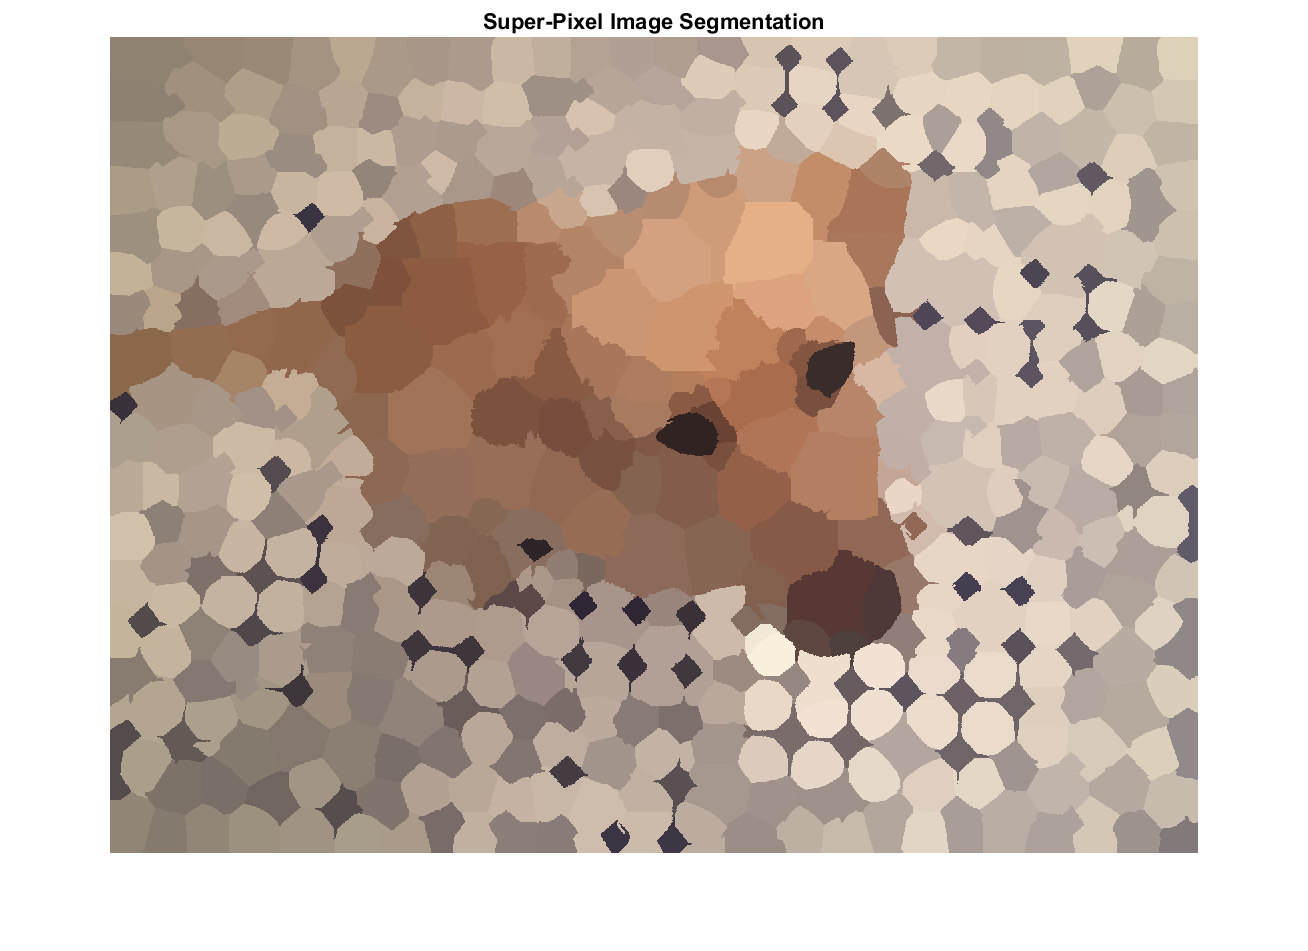

pixel_num = 500;
img_spr_pxl = spr_pxl_img(img_db,pixel_num);
figure;
imshow(img_spr_pxl);
title('Super-Pixel Image Segmentation');

Image segmentation using CRF model

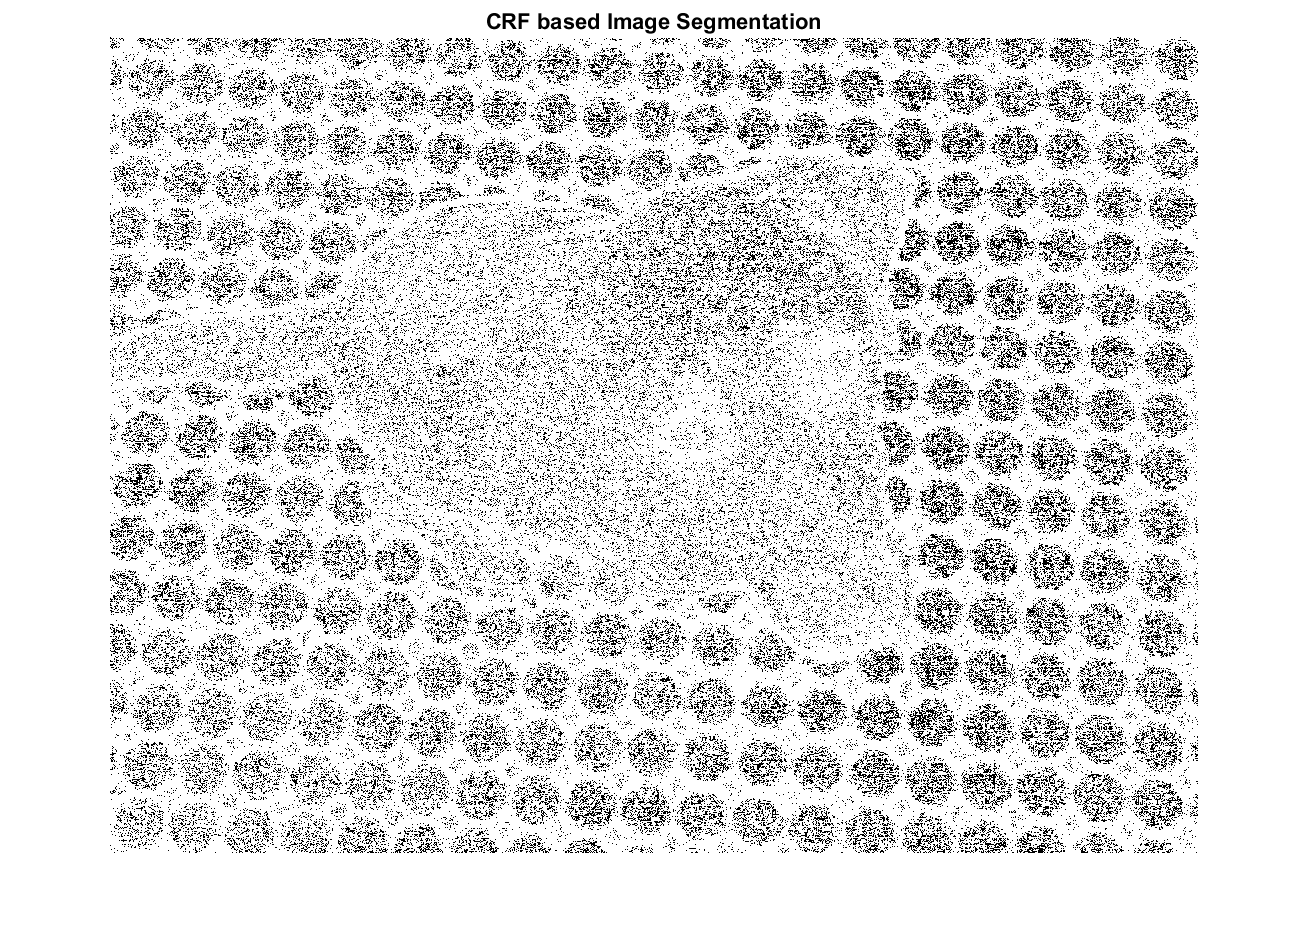

class_number = 2;
unary_cnst = 1;
pair_cnst = 0.8;
maxIter = 5;
crf_seg = ICM_crf(img_db,class_number,unary_cnst,pair_cnst,maxIter);
figure;
imshow(crf_seg,[]);
title('CRF based Image Segmentation');

CRF + superpixel model

% img4_spr_pxl = imread('peppers.png');
% sp_img = spr_pxl_img(img4_spr_pxl,100);
% sp_img_db = im2double(sp_img);
% figure;
% imshow(sp_img);
% title('Super Pixel Image')
% class_number = 8;
% unary_cnst = 0.5;
% pair_cnst = 1;
% maxIter = 30;
% seg = ICM_crf(sp_img_db,class_number,unary_cnst,pair_cnst,maxIter);
% figure;
% imshow(seg,[]);
% title('Segmentation on Super Pixel Image')

CRF + superpixel + color features model

% img4_spr_pxl = imread('peppers.png');
% sp_img = spr_pxl_img(img4_spr_pxl,100);
% lab_pprs = rgb2lab(sp_img);
% lab_pprs_db = im2double(lab_pprs);
% figure;
% imshow(lab_pprs);
% title('Super Pixel Image with intensity feature')
% class_number = 8;
% unary_cnst = 0.5;
% pair_cnst = 1;
% maxIter = 3;
% ab = lab_pprs(:,:,2) - lab_pprs(:,:,3);
% im_ab = im2double(ab);
% seg = ICM_crf(im_ab,class_number,unary_cnst,pair_cnst,maxIter);
% figure;
% imshow(seg,[]);
% title('Segmentation on Super Pixel Image')

CRF + superpixel + intensity features model

%y

CRF + superpixel + texture features model

%z

Iterated Condition Model for CRF

function segmentation = ICM_crf(image,class_number,unary_cnst,pair_cnst,maxIter)
[width,height,bands] = size(image);
image = imstack2vectors(image);
[segmentation,c] = kmeans(image,class_number);
clear c;
iter = 0;
while(iter < maxIter)
    Eu = unary_potential(image,segmentation,unary_cnst);
    Ep = pairwise_potential(image,segmentation,pair_cnst);
    E = Eu + Ep;
    segmentation = exp(E);
    [tm,segmentation] = min(segmentation,[],2);
    iter = iter+1;
end
segmentation = reshape(segmentation,[width height]);
end

Stack image to vectors

function [X, R] = imstack2vectors(S, MASK)
[M, N, n] = size(S);
if nargin == 1
   MASK = true(M, N);
else
   MASK = MASK ~= 0;
end

[I, J] = find(MASK);
R = [I, J];

Q = M*N;
X = reshape(S, Q, n);

MASK = reshape(MASK, Q, 1);

X = X(MASK, :);
end

Mapping image to super pixel image 

function spr_pxl_img = spr_pxl_img(img,N)
[L,N] = superpixels(img,N);
outputImage = zeros(size(img),'like',img);
idx = label2idx(L);
numRows = size(img,1);
numCols = size(img,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(img(redIdx));
    outputImage(greenIdx) = mean(img(greenIdx));
    outputImage(blueIdx) = mean(img(blueIdx));
end    
spr_pxl_img = outputImage;
end

Unary potential

function unary_vctr = unary_potential(image,segmentation,unary_cnst)
N = size(image,1);
unary_cnst_vctr = unary_cnst.*ones(N,1);
ftr = mean(image,2);
up_vctr = [segmentation ftr.*segmentation];
unary_vctr = up_vctr.*unary_cnst_vctr;
end

Pair-wise potential

function pair_vctr = pairwise_potential(image,segmentation,pair_cnst)
n = size(segmentation,1);
pair_cnst_vctr = pair_cnst.*ones(n,1);
prev_seg = [segmentation(1) ;segmentation(1:n-1)];
num = segmentation.*prev_seg;
ftr = mean(image,2);
prev_img = [ftr(1) ;ftr(1:size(ftr)-1)];
dnm = abs(ftr - prev_img);
up_vctr = num./(num.*dnm);
pair_vctr = up_vctr.*pair_cnst_vctr;
end